Problem 1

syms x sigma mu
%lets use same values in all computations
sigma = 1

sigma = 1

mu = 1

mu = 1


%normal distribution
N  =  1/(sigma*sqrt(2*pi))*exp(-1/2*((x-mu)/sigma)^2);
%
for degree = 0:5
    degree
    exact_result = round(int(gg(x,degree)*N,x,-inf,inf),10)
    approximation = round(2/3*gg(mu,degree) + 1/6*gg(mu + sigma*sqrt(3),degree) + 1/6*gg(mu - sigma*sqrt(3),degree),10)
end

degree = 0

$$exact\_result = 1.0$$

approximation = 1

degree = 1

$$exact\_result = 1.0$$

approximation = 1

degree = 2

$$exact\_result = 2.0$$

approximation = 2

degree = 3

$$exact\_result = 4.0$$

approximation = 4

degree = 4

$$exact\_result = 10.0$$

approximation = 10

degree = 5

$$exact\_result = 26.0$$

approximation = 26

Problem 2

clear all;
rng('default'); rng(0) % set the random number generator's starting value
g=9.81;        % gravity acceleration constant
qc=1;          % power spectral density of white noise excitation
r=0.1;         % measurement noise variance
x0=[1.5;0];    % initial state (radian angle and angular velocity)
DT=0.01;       % time step size
nk=500;        % number of steps
T=(1:nk)*DT;   % timestamps
X=zeros(1,nk); % preallocate
Y=NaN(1,nk);   % preallocate using not-a-number
m=5;           % number of time steps per measurement
% In the state generation, use the leapfrog method instead of the Euler-Maruyama method.  
u=x0(1); v=x0(2);
for k=1:nk
    u=u+DT/2*v; 
    v=v-g*DT*sin(u)+randn*sqrt(qc*DT);
    u=u+DT/2*v;
    if ~rem(k,m)
        Y(k)=sin(u)+sqrt(r)*randn;
    end
    X(k)=u;
end
% Filter
m0=[1.6;0];    
P0=0.1*eye(2);
Q=qc*[DT^3/4, DT^2/2; DT^2/2, DT];
R=r;
filtername={'GHKF'};                   % *** CHANGED ***
GA={@GaussApproxGHKF};       % *** CHANGED ***
nf=length(filtername);
M1f=zeros(nf,nk);
for jf=1:nf   % loop for different filters
    m=m0; P=P0;
    for k=1:nk   % filter
        [m,P]=gf_predict(m,P,@pendulum_f_leapfrog,Q,GA{jf});
        [m,P]=gf_update(m,P,Y(k),@pendulum_h,R,GA{jf});
        M1f(jf,k)=m(1);
    end
    rmse=sqrt(mean((X(1,:)-M1f(jf,:)).^2));
    disp(['RMS error for ' filtername{jf} ' is ' num2str(rmse)])
end

RMS error for GHKF is 0.16963


Plot

% Plot
plot(T,Y,'b.', ...
    [0,T],[x0(1),X(1,:)],'r-',...
    [0,T],[m0(1),M1f(1,:)],'k-','linewidth',2,'markersize',20);
xlabel('Time')
ylabel({'angle';'(rad)'},'rot',0)
legend('data','true',filtername{1},'location','SW')

Problem 3

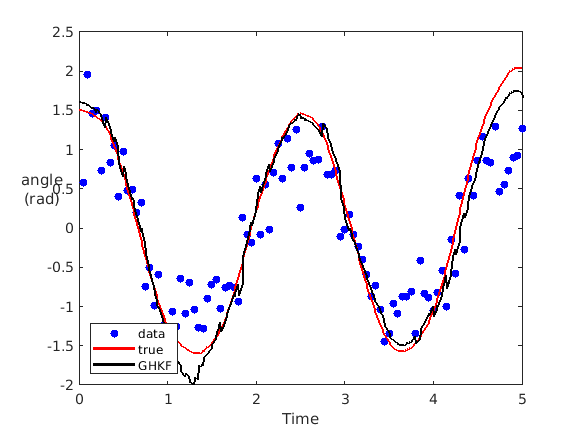

Simulation 1


RMS error for UKF is 0.26428


RMS error for PF  is 0.23851


RMS error for PS  is 0.16631


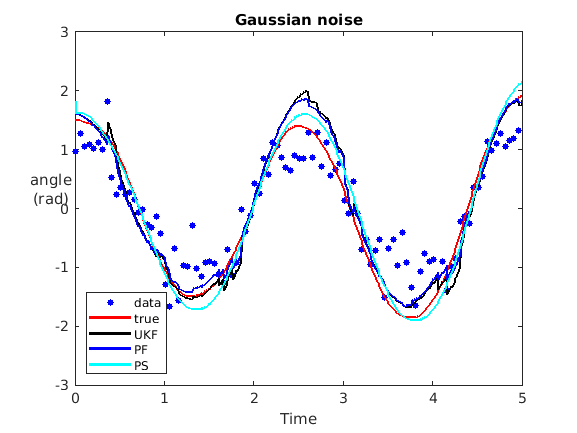

Simulation 2


RMS error for UKF is 1.6055


RMS error for PF  is 0.29611


RMS error for PS  is 0.20451


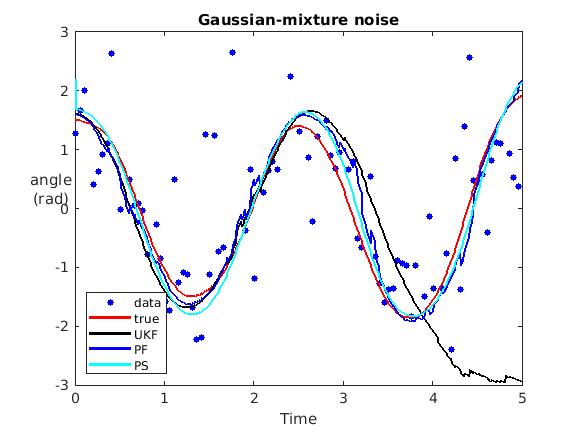

clear all;

% Define simulation parameters

g=9.81;        % gravity acceleration constant
qc=1;          % power spectral density of white noise excitation
r=0.1;         % measurement variance
x0=[1.5;0];    % initial state (radian angle and angular velocity)
DT=0.01;       % time step size
nk=500;        % number of steps
mskip=5;       % number of time steps per measurement
noise={ makedist('Normal','sigma',sqrt(r))
    gmdistribution([0;0],cat(3,r,16/3),[0.5,0.5])};

simTitle={'Gaussian noise','Gaussian-mixture noise'};

for isim=1:length(noise)
    disp(['Simulation ',num2str(isim)])
    rng('default'); rng(0)      % random number generator's starting value
    
    % Track
    T=(1:nk)*DT;   % timestamps
    X=zeros(2,nk); % preallocate
    x=x0;
    for k=1:nk
        x=x+DT*[x(2);-g*sin(x(1))]+[0;sqrt(qc*DT)*randn];
        X(:,k)=x;
    end
    
    % Measurements
    Y=NaN(1,nk);   % preallocate using not-a-number
    for k=1:mskip:nk
        Y(k)=sin(X(1,k))+random(noise{isim});
    end
    
    % Filter parameters
    m0 = [1.6;0];       % slightly off from x0
    P0 = 0.1*eye(2);
    Q=qc*[DT^3/3 0;0 DT];   % slightly off, nonsingular for PS
    if isim==2
        % variance of univariate gaussian mixture with zero-mean components
        R=(noise{isim}.PComponents)*(squeeze(noise{isim}.Sigma).^2);
    else
        R=var(noise{isim});
    end
    N=1000;              % number of particles
    nbs=4;              % number of PS backward simulations
    M=zeros(3,nk);      % preallocate the array of estimated angles
    
    %  UKF
    m=m0; P=P0;
    for k=1:nk
        [m,P]=gf_predict(m,P,@pendulum_f,Q,@GaussApproxUKF);
        if ~isnan(Y(k))
            [m,P]=gf_update(m,P,Y(k),@pendulum_h,R,@GaussApproxUKF);
        end
        M(1,k)=m(1);
    end
    rmse=sqrt(mean((X(1,:)-M(1,:)).^2));
    disp(['RMS error for UKF is ' num2str(rmse)])
    
    % Particle filter
    xx=mvnrnd(repmat(m0,1,N)',P0)';
    xpf=zeros(length(m0),N,nk+1); xpf(:,:,1)=xx;
    for k=1:nk
        xx=mvnrnd(pendulum_f(xx)',Q)';
        if ~isnan(Y(k))
            w=pdf(noise{isim},(repmat(Y(k),1,N)-pendulum_h(xx))')';
            w=w/sum(w);
            xx=xx(:,resampstr(w)); % stratified resampling
        end
        xpf(:,:,k+1)=xx;
        M(2,k)=mean(xx(1,:));
    end
    rmse=sqrt(mean((X(1,:)-M(2,:)).^2));
    disp(['RMS error for PF  is ',num2str(rmse)])
    
    % Backward-simulation particle smoother
    xs=xpf(:,randi(N,1,nbs),nk+1);
    for k=nk:-1:1
        for j=1:nbs
            w=mvnpdf(repmat(xs(:,j),1,N)',pendulum_f(xpf(:,:,k))',Q)';
            w=w/sum(w);
            [~,J]=histc(rand,[0;cumsum(w(:))]); % a sample from 1:N
            xs(:,j)=xpf(:,J,k);
        end
        M(3,k)=mean(xs(1,:),2);
    end
    rmse=sqrt(mean(([x0(1) X(1,:)]-[M(3,:) M(2,end)]).^2));
    disp(['RMS error for PS  is ',num2str(rmse)])
   
    
    % Plot the results
    figure(isim),clf
    plot(T,Y,'b.', ...
        [0,T],[x0(1),X(1,:)],'r-',...
        [0,T],[m0(1),M(1,:)],'k-',...
        [0,T],[m0(1),M(2,:)],'b-',...
        [0,T],[ M(2,end) M(3,:) ],'c-',...
        'linewidth',2,'markersize',16);
    
    title(simTitle{isim})
    
    axis([0 5 -3 3])
    xlabel('Time')
    ylabel({'angle';'(rad)'},'rot',0)
    legend('data','true','UKF','PF','PS','location','SW')
    
    
end

Problem 4

clear all;

rng('default'); rng(0) % set the random number generator's starting value
g=9.81;        % gravity acceleration constant
qc=1;          % power spectral density of white noise excitation
r=0.1;         % measurement noise variance
x0=[1.5;0];    % initial state (radian angle and angular velocity)
DT=0.01;       % time step size
nk=500;        % number of steps
T=(1:nk)*DT;   % timestamps
X=zeros(1,nk); % preallocate
Y=NaN(1,nk);   % preallocate using not-a-number
m=5;           % number of time steps per measurement
% In the state generation, use the leapfrog method instead of the Euler-Maruyama method.  
u=x0(1); v=x0(2);
for k=1:nk
    u=u+DT/2*v; 
    v=v-g*DT*sin(u)+randn*sqrt(qc*DT);
    u=u+DT/2*v;
    if ~rem(k,m)
        Y(k)=sin(u)+sqrt(r)*randn;
    end
    X(k)=u;
end

m0=[1.6;0];    
P0=0.1*eye(2);
Q=qc*[DT^3/4, DT^2/2; DT^2/2, DT];
R=r;

noise=gmdistribution([0;0],cat(3,r,16/3),[0.5,0.5]);

N=1000; M=zeros(1,nk);
x=mvnrnd(repmat(m0,1,N)',P0)';
w=repmat(1/N,1,N);
for k=1:nk
 x=mvnrnd(pendulum_f_leapfrog(x)',Q)';
 if ~isnan(Y(k))
 YY=repmat(Y(k),1,N);
 w=pdf(noise,(YY-pendulum_h(x))')';
 w=w/sum(w);
 x=x(:,resampstr(w));
 w=repmat(1/N,1,N);
 end
 M(k)=mean(x(1,:));
end

rmse=sqrt(mean((X(1,:)-M(1,:)).^2));
disp(['RMS error for bootstrap filter is ' num2str(rmse)])

RMS error for bootstrap filter is 0.18856


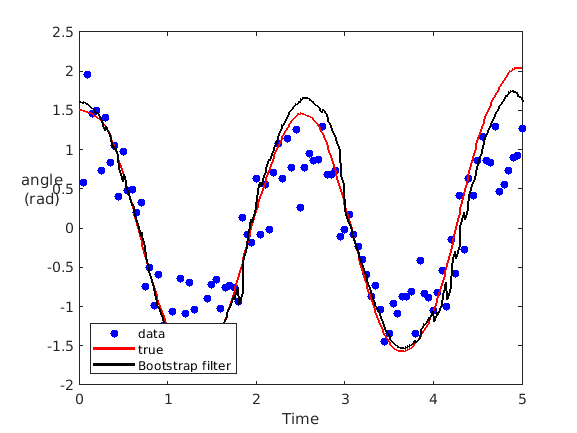

    
%plot
plot(T,Y,'b.', ...
    [0,T],[x0(1),X(1,:)],'r-',...
    [0,T],[m0(1),M(1,:)],'k-','linewidth',2,'markersize',20);
xlabel('Time')
ylabel({'angle';'(rad)'},'rot',0)
legend('data','true','Bootstrap filter','location','SW')

Problem 5

clear all;
rng(0);

DT=0.1; nk=100; Qc=1; r=0.1; x0=[4;0];
T=(1:nk)*DT; X=zeros(1,nk); Y=zeros(1,nk);
Ak=[1,DT;0,1]; Qk=Qc*[DT^3/3,DT^2/2;DT^2/2,DT];
x=x0;
for k=1:nk
    x=mvnrnd(Ak*x,Qk)'; X(k)=x(1);
    %Y(k)=norm([0.5-x(1);0.1])+sqrt(r)*randn;
    Y(k) = tracking_h(x) + sqrt(r)*randn;
end

m0=[4;0];    
P0=0.01*eye(2);
noise=gmdistribution([0;0],cat(3,r,16/3),[0.5,0.5]);

N=1000; M=zeros(1,nk);
x=mvnrnd(repmat(m0,1,N)',P0)';
w=repmat(1/N,1,N);
for k=1:nk
 x=mvnrnd(tracking_f(x)',Qk)';
 if ~isnan(Y(k))
 YY=repmat(Y(k),1,N);
 w=pdf(noise,(YY-tracking_h(x))')';
 w=w/sum(w);
 x=x(:,resampstr(w));
 w=repmat(1/N,1,N);
 end
 M(k)=mean(x(1,:));
end

rmse=sqrt(mean((X(1,:)-M(1,:)).^2));
disp(['RMS error for bootstrap filter is ' num2str(rmse)])

RMS error for bootstrap filter is 0.15648


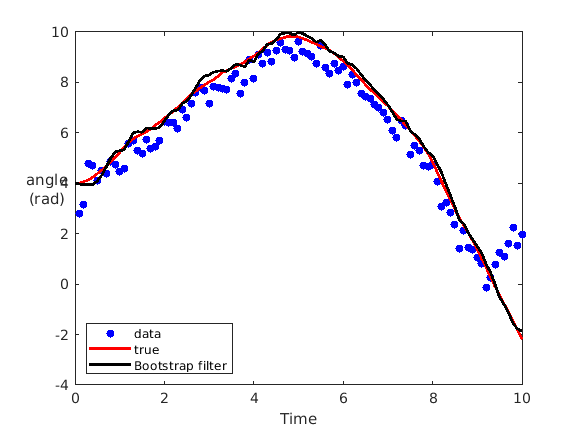

    
%plot
plot(T,Y,'b.', ...
    [0,T],[x0(1),X(1,:)],'r-',...
    [0,T],[m0(1),M(1,:)],'k-','linewidth',2,'markersize',20);
xlabel('Time')
ylabel({'angle';'(rad)'},'rot',0)
legend('data','true','Bootstrap filter','location','SW')

Problem 6

clear all;
rng(0);

DT=0.1; nk=100; Qc=1; r=0.1; x0=[4;0];
T=(1:nk)*DT; X=zeros(1,nk); Y=zeros(1,nk);
Ak=[1,DT;0,1]; Qk=Qc*[DT^3/3,DT^2/2;DT^2/2,DT];
x=x0;
for k=1:nk
    x=mvnrnd(Ak*x,Qk)'; X(k)=x(1);
    Y(k) = tracking_h_P6(x) + sqrt(r)*randn; %measurement with noise
end

m0=[4;0];    
P0=diag([400,1]);
noise=gmdistribution([0;0],cat(3,r,16/3),[0.5,0.5]);

N=5000; M=zeros(1,nk);
x=mvnrnd(repmat(m0,1,N)',P0)';
w=repmat(1/N,1,N);
for k=1:nk
 x=mvnrnd(tracking_f_P6(x)',Qk)';
 if ~isnan(Y(k))
 YY=repmat(Y(k),1,N);
 w=pdf(noise,(YY-tracking_h_P6(x))')';
 w=w/sum(w);
 x=x(:,resampstr(w));
 w=repmat(1/N,1,N);
 end
 M(k)=mean(x(1,:));
end

rmse=sqrt(mean((X(1,:)-M(1,:)).^2));
disp(['RMS error for bootstrap filter is ' num2str(rmse)])

RMS error for bootstrap filter is 1.9487


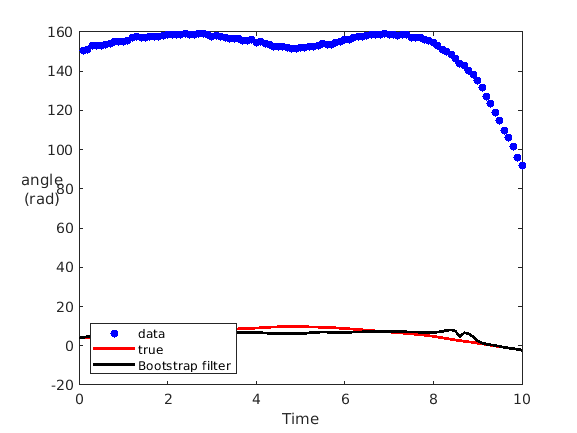

    
%plot
plot(T,Y,'b.', ...
    [0,T],[x0(1),X(1,:)],'r-',...
    [0,T],[m0(1),M(1,:)],'k-','linewidth',2,'markersize',20);
xlabel('Time')
ylabel({'angle';'(rad)'},'rot',0)
legend('data','true','Bootstrap filter','location','SW')

Functions

Problem 1 function

function fval = gg(x,degree)
    fval = x.^degree;
end

Problem 2 functions

function [m,P]=gf_predict(m,P,f,Q,GaussApprox)
[m,P]=GaussApprox(m,P,f,Q);
end

function [m,P]=gf_update(m,P,y,h,R,GaussApprox)
if ~isnan(y)
    [mu,S,C]=GaussApprox(m,P,h,R);
    K=C/S;
    P=P-K*S*K';
    m=m+K*(y-mu);
end
end

function [mu,S,C,X]=GaussApproxUKF(m,P,g,E)
nx=length(m);
alpha=1; beta=0; kappa=max(3-nx,1);
lambda=alpha^2*(nx+kappa)-nx;
WM=repmat(0.5/(nx+lambda),2*nx+1,1);
WM(1)=lambda/(nx+lambda);
WC=WM; WC(1)=lambda/(nx+lambda)+1-alpha^2+beta;
A=chol(P,'lower');   % use schol if P is singular
X=[m repmat(m,1,2*nx)+sqrt(lambda+nx)*[A -A]];
Y=g(X); ny=size(Y,1);
mu=zeros(ny,1); S=E; C=zeros(nx,ny);
for i=1:length(WM)
    mu=mu+WM(i)*Y(:,i);
end
for i=1:length(WC)
    S=S+WC(i)*(Y(:,i)- mu)*(Y(:,i) - mu)';
    C=C+WC(i)*(X(:,i)-m)*(Y(:,i) - mu)';
end
end

%third order GHKF, p = 3
function [mu,S,C,X]=GaussApproxGHKF(m,P,g,E)
n=length(m); p=3;
W1 = [2/3,1/6,1/6];
xi1 = [0,sqrt(3),-sqrt(3)];
num=0:(p^n-1); ind=zeros(n,p^n);
for i=1:n, ind(i,:)=rem(num,p)+1; num=floor(num/p); end
XI=xi1(ind); W=prod(W1(ind),1);
X=repmat(m,1,p^n)+chol(P,'lower')*XI;
Y=g(X); ny=size(Y,1);
mu=zeros(ny,1); S=E; C=zeros(n,ny);
for i=1:length(W),mu=mu+W(i)*Y(:,i); end
for i=1:length(W)
    S=S+W(i)*(Y(:,i)-mu)*(Y(:,i)-mu)';
    C=C+W(i)*(X(:,i)-mu)*(Y(:,i)-mu)';
end
end

Problem 2 function

function fval=pendulum_f_leapfrog(x)
DT=0.01; g=9.81;
fval = [1 DT;0 1]*x - [DT/2; 1]*g*DT*sin([1 DT/2]*x);
end

Problem 3 functions

function J=resamp(W)
u=rand(length(W),1);
[~,J]=histc(u,[0;cumsum(W(:))]);
end

function J=resampstr(W)
N=length(W); u=((0:N-1)'+rand(N,1))/N;
[~,J]=histc(u,[0;cumsum(W(:))]);
end

Problem 5 functions

function fval=tracking_f(x)
DT = 0.1;
fval = [1 DT; 0 1]*x;
end

function hval=tracking_h(x)
hval = sqrt((0.5-x(1,:)).^2+0.01);
end

Problem 6 functions

function fval=tracking_f_P6(x)
DT = 0.1;
fval = [1 DT; 0 1]*x;
end

function hval=tracking_h_P6(x)
hval = 100 + 50*sin(x(1,:)/7) + 20*sin(x(1,:)/5) + 20*cos(x(1,:)/4) + sin(x(1,:));
end

function fval=pendulum_f(x)
DT=0.01; g=9.81;
fval=x+DT*[ x(2,:)
    -g*sin(x(1,:))];
end

function hval=pendulum_h(x)
hval=sin(x(1,:));
end